# Cardiac segmentation adjustment

% Stardist

basePath = 'E:\Cardiac_201\round1\';
outputPath = 'E:\Cardiac_201\output\';

dirs = dir(strcat(basePath, 'position*'));
dirs = struct2table(dirs);
dirs = natsort(dirs.name);
se = strel('disk', 4);

Ncells = 0;
Volumes = [];

for p=1:numel(dirs)
% for p=1:1
    tic
    curr_dir = dirs{p};
    fprintf('Loading %s...', curr_dir);
    curr_files = dir(fullfile(basePath, curr_dir, 'output', 'stardist_output', '*.tif'));
    curr_files = struct2table(curr_files);
    curr_files = natsort(curr_files.name);
    seg_mask = uint16(zeros(1024, 1024, numel(curr_files)));
    for c=1:numel(curr_files)
        %curr_files{c}
        curr_path = fullfile(basePath, curr_dir, 'output', 'stardist_output', curr_files{c});
        curr_img = imread(curr_path);
        input_img = imdilate(curr_img, se);
        bmask = boundarymask(input_img);
%         input_img = label2rgb(input_img);
%         input_img = imcomplement(input_img);
%         input_img = rgb2gray(input_img);
        base_bw = imbinarize(input_img,0);
        base_bw = imfill(base_bw, 'holes');
        bmask = imcomplement(bmask);
        out_bw = base_bw .* bmask;
        out_bw = bwareaopen(out_bw, 200);
%         figure()
%         imshow(out_bw)
        seg_mask(:,:,c)=out_bw;
    end
    
    % compute center stack
    seg_bw = imbinarize(seg_mask);
    center_stack = zeros(size(seg_bw));

    for z=1:size(seg_bw,3)
        curr_slice = seg_bw(:,:,z);
        curr_centroid = regionprops(curr_slice, 'Centroid');
        curr_centroid = struct2table(curr_centroid);
        curr_centroid = int16(curr_centroid.Centroid);
       
        curr_center = get_spot_img(curr_slice, curr_centroid, [5 5]); % adjust merge level
        center_stack(:,:,z) = curr_center;
    end
    
    center_stack = imbinarize(center_stack);
    
    % compute adjusted label stack
    label_stack = bwlabeln(center_stack, 6);
    
    curr_cells = numel(unique(label_stack)) - 1;
    Ncells = Ncells + curr_cells;
    fprintf(sprintf('Number of cells: %d', curr_cells));
    
    output_img = zeros(size(center_stack));
    
    for z=1:size(center_stack,3)
        curr_seg = seg_bw(:,:,z);
        curr_center = label_stack(:,:,z);
        curr_slice = output_img(:,:,z);
        
        curr_stat = regionprops(curr_seg, 'PixelIdxList');
        for i=1:numel(curr_stat)
            curr_cc = curr_stat(i).PixelIdxList;
            curr_label = unique(curr_center(curr_cc));
            if numel(curr_label) == 1
                curr_slice(curr_cc) = curr_label;
            else
                curr_label = curr_label(curr_label~=0);
                curr_slice(curr_cc) = curr_label(1);
            end
        end
        output_img(:,:,z) = curr_slice;
    end
    
    curr_volume = regionprops3(output_img, "Volume");
    Volumes = [Volumes; curr_volume.Volume]; 
    
    curr_out_dir = fullfile(outputPath, 'stardist_5', curr_dir);
    if ~exist(curr_out_dir, 'dir')
        mkdir(curr_out_dir);
    end
    
    label_fname = fullfile(curr_out_dir, 'label_img.tif');
    if exist(label_fname, 'file') == 2
        delete(label_fname);
    end
    for z=1:size(output_img,3)        
        imwrite(uint16(output_img(:,:,z)), label_fname, 'writemode', 'append');        
    end
    
    seg_fname = fullfile(curr_out_dir, 'seg_img.tif');
    if exist(seg_fname, 'file') == 2
        delete(seg_fname);
    end
    for z=1:size(seg_mask,3)        
        imwrite(uint16(seg_mask(:,:,z)), seg_fname, 'writemode', 'append');        
    end
    
    fprintf(sprintf('[time = %.2f s]\n', toc));
end

figure
histogram(Volumes)

figure
histfit(Volumes)

fprintf(sprintf('Number of cells total: %d\n', Ncells));
stat = [mean(Volumes), median(Volumes), std(Volumes), range(Volumes)];
fprintf(sprintf(['Mean: %.2f\n' ...
    'Median: %.2f\n'...
    'Std: %.2f\n'...
    'Range: %.2f'], stat));


% Watershed

basePath = 'E:\Cardiac_201\output\watershed\';
outputPath = 'E:\Cardiac_201\output\';
dirs = dir(strcat(basePath, 'position*'));
dirs = struct2table(dirs);
dirs = natsort(dirs.name);
se = strel('disk', 4);

Ncells = 0;
Volumes = [];

for p=1:numel(dirs) % for each position
%for p=1:1 % test
    tic
    curr_dir = dirs{p};
    fprintf('Loading %s...', curr_dir);
    curr_file = fullfile(basePath, curr_dir, 'label_img.tif');
    curr_label = new_LoadMultipageTiff(curr_file, 'uint16', false);
    out_label = zeros(size(curr_label));
    
    for z=1:size(curr_label,3)
        out_label(:,:,z) = imdilate(curr_label(:,:,z), se);
    end
    
    curr_volume = regionprops3(out_label, "Volume");
    Volumes = [Volumes; curr_volume.Volume]; 
    
    curr_cells = numel(unique(out_label)) - 1;
    Ncells = Ncells + curr_cells;
    fprintf(sprintf('Number of cells: %d', curr_cells));

    curr_out_dir = fullfile(outputPath, 'watershed_dilated', curr_dir);
    if ~exist(curr_out_dir, 'dir')
        mkdir(curr_out_dir);
    end
    
    label_fname = fullfile(curr_out_dir, 'label_img.tif');
    if exist(label_fname, 'file') == 2
        delete(label_fname);
    end
    
    for z=1:size(out_label,3)        
        imwrite(uint16(out_label(:,:,z)), label_fname, 'writemode', 'append');        
    end
    
    fprintf(sprintf('[time = %.2f s]\n', toc));
end

figure
histogram(Volumes)

figure
histfit(Volumes)

fprintf(sprintf('Number of cells total: %d\n', Ncells));
stat = [mean(Volumes), std(Volumes), range(Volumes)];
fprintf(sprintf(['Mean: %.2f\n' ...
    'Median: %.2f\n'...
    'Std: %.2f'], stat));

% thick tissue
basePath = 'C:\Users\jiahao\Data\BS10\output\registered_crop\round1\';
outputPath = 'C:\Users\jiahao\Data\BS10\output\';

se = strel('disk', 1);

Ncells = 0;
Volumes = [];

tic
curr_dir = basePath;
fprintf('Loading %s...', curr_dir);

Loading C:\Users\jiahao\Data\BS10\output\registered_crop\round1\...

curr_files = dir(fullfile(basePath, 'output', 'stardist_output', '*.tif'));
curr_files = struct2table(curr_files);
curr_files = natsort(curr_files.name)

curr_files = 100×1 cell array
    {'label_1.tif' }
    {'label_2.tif' }
    {'label_3.tif' }
    {'label_4.tif' }
    {'label_5.tif' }
    {'label_6.tif' }
    {'label_7.tif' }
    {'label_8.tif' }
    {'label_9.tif' }
    {'label_10.tif'}
    {'label_11.tif'}
    {'label_12.tif'}
    {'label_13.tif'}
    {'label_14.tif'}
    {'label_15.tif'}
    {'label_16.tif'}
    {'label_17.tif'}
    {'label_18.tif'}
    {'label_19.tif'}
    {'label_20.tif'}
    {'label_21.tif'}
    {'label_22.tif'}
    {'label_23.tif'}
    {'label_24.tif'}
    {'label_25.tif'}
    {'label_26.tif'}
    {'label_27.tif'}
    {'label_28.tif'}
    {'label_29.tif'}
    {'label_30.tif'}


seg_mask = uint16(zeros(1700, 1700, numel(curr_files)));
for c=1:numel(curr_files)
    %curr_files{c}
    curr_path = fullfile(basePath, 'output', 'stardist_output', curr_files{c});
    curr_img = imread(curr_path);
    input_img = imdilate(curr_img, se);
    bmask = boundarymask(input_img);
%         input_img = label2rgb(input_img);
%         input_img = imcomplement(input_img);
%         input_img = rgb2gray(input_img);
    base_bw = imbinarize(input_img, 0);
    base_bw = imfill(base_bw, 'holes');
    bmask = imcomplement(bmask);
    out_bw = base_bw .* bmask;
    out_bw = bwareaopen(out_bw, 1);
%         figure()
%         imshow(out_bw)
    seg_mask(:,:,c)=out_bw;
end

% compute center stack
seg_bw = imbinarize(seg_mask);
center_stack = zeros(size(seg_bw));

for z=1:size(seg_bw,3)
    curr_slice = seg_bw(:,:,z);
    curr_centroid = regionprops(curr_slice, 'Centroid');
    curr_centroid = struct2table(curr_centroid);
    curr_centroid = int16(curr_centroid.Centroid);
   
    curr_center = get_spot_img(curr_slice, curr_centroid, [2 2]); % adjust merge level
    center_stack(:,:,z) = curr_center;
end

center_stack = imbinarize(center_stack);

% compute adjusted label stack
label_stack = bwlabeln(center_stack, 6);

curr_cells = numel(unique(label_stack)) - 1;
Ncells = Ncells + curr_cells;
fprintf(sprintf('Number of cells: %d', curr_cells));

Number of cells: 42142


output_img = zeros(size(center_stack));

for z=1:size(center_stack,3)
    curr_seg = seg_bw(:,:,z);
    curr_center = label_stack(:,:,z);
    curr_slice = output_img(:,:,z);
    
    curr_stat = regionprops(curr_seg, 'PixelIdxList');
    for i=1:numel(curr_stat)
        curr_cc = curr_stat(i).PixelIdxList;
        curr_label = unique(curr_center(curr_cc));
        if numel(curr_label) == 1
            curr_slice(curr_cc) = curr_label;
        else
            curr_label = curr_label(curr_label~=0);
            curr_slice(curr_cc) = curr_label(1);
        end
    end
    output_img(:,:,z) = curr_slice;
end

curr_volume = regionprops3(output_img, ["Volume", "VoxelIdxList"]);

new_label = 1

new_label = 1

trash_label = 1

trash_label = 1

filtered_output_img = zeros(size(center_stack));
trash_output_img = zeros(size(center_stack));

for i=1:size(curr_volume, 1)
    if table2array(curr_volume(i,"Volume")) > 300
        curr_idx = table2array(curr_volume(i,"VoxelIdxList"));
        filtered_output_img(curr_idx{1}) = new_label;
        new_label = new_label + 1;
    else
        curr_idx = table2array(curr_volume(i,"VoxelIdxList"));
        trash_output_img(curr_idx{1}) = trash_label;
        trash_label = trash_label + 1; 
    end
end

filtered_volume = regionprops3(filtered_output_img, "Volume");
size(filtered_volume,1)

ans = 26550

% Volumes = [Volumes; filtered_volume.Volume]; 

curr_out_dir = fullfile(outputPath, 'stardist_2_crop');
if ~exist(curr_out_dir, 'dir')
    mkdir(curr_out_dir);
end

label_fname = fullfile(curr_out_dir, 'label_img.tif');
if exist(label_fname, 'file') == 2
    delete(label_fname);
end
for z=1:size(output_img,3)        
    imwrite(uint16(output_img(:,:,z)), label_fname, 'writemode', 'append');        
end

filtered_label_fname = fullfile(curr_out_dir, 'filtered_label_img.tif');
if exist(filtered_label_fname, 'file') == 2
    delete(filtered_label_fname);
end
for z=1:size(filtered_output_img,3)        
    imwrite(uint16(filtered_output_img(:,:,z)), filtered_label_fname, 'writemode', 'append');        
end

trash_label_fname = fullfile(curr_out_dir, 'trash_label_img.tif');
if exist(trash_label_fname, 'file') == 2
    delete(trash_label_fname);
end
for z=1:size(filtered_output_img,3)        
    imwrite(uint16(trash_output_img(:,:,z)), trash_label_fname, 'writemode', 'append');        
end

seg_fname = fullfile(curr_out_dir, 'seg_img.tif');
if exist(seg_fname, 'file') == 2
    delete(seg_fname);
end
for z=1:size(seg_mask,3)        
    imwrite(uint16(seg_mask(:,:,z)), seg_fname, 'writemode', 'append');        
end

fprintf(sprintf('[time = %.2f s]\n', toc));

[time = 99.48 s]


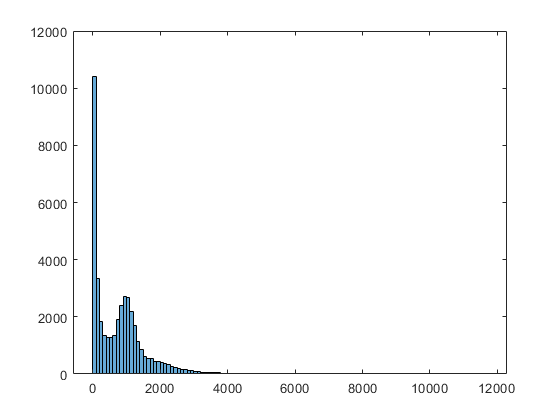



figure
histogram(curr_volume.Volume)

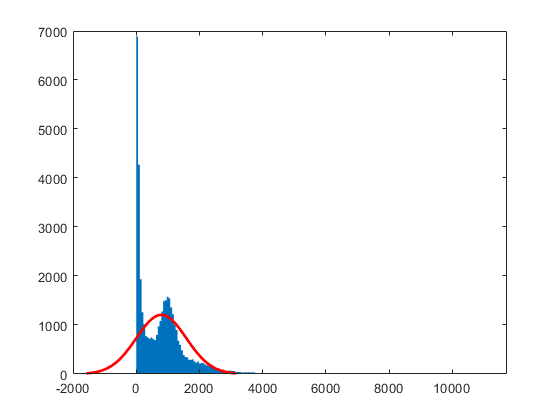


figure
histfit(curr_volume.Volume)

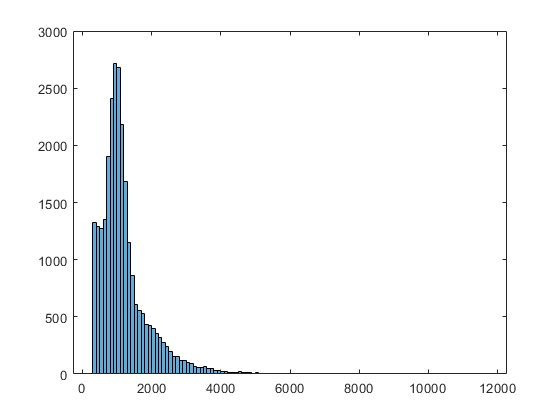


figure
histogram(filtered_volume.Volume)

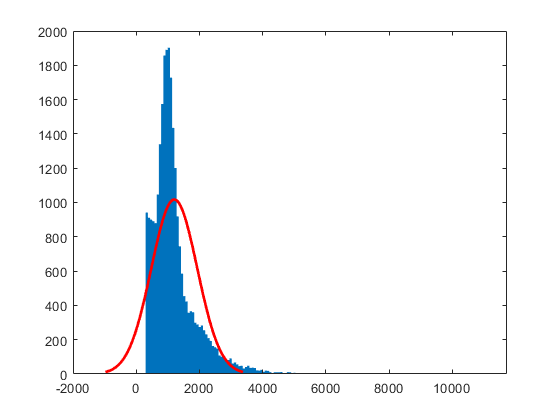


figure
histfit(filtered_volume.Volume)


fprintf(sprintf('Number of cells total: %d\n', Ncells));

Number of cells total: 42142


stat = [mean(Volumes), median(Volumes), std(Volumes), range(Volumes)];
fprintf(sprintf(['Mean: %.2f\n' ...
    'Median: %.2f\n'...
    'Std: %.2f\n'...
    'Range: %.2f'], stat));

Mean: NaN
Median: NaN
Std: NaN
Range: 